clear

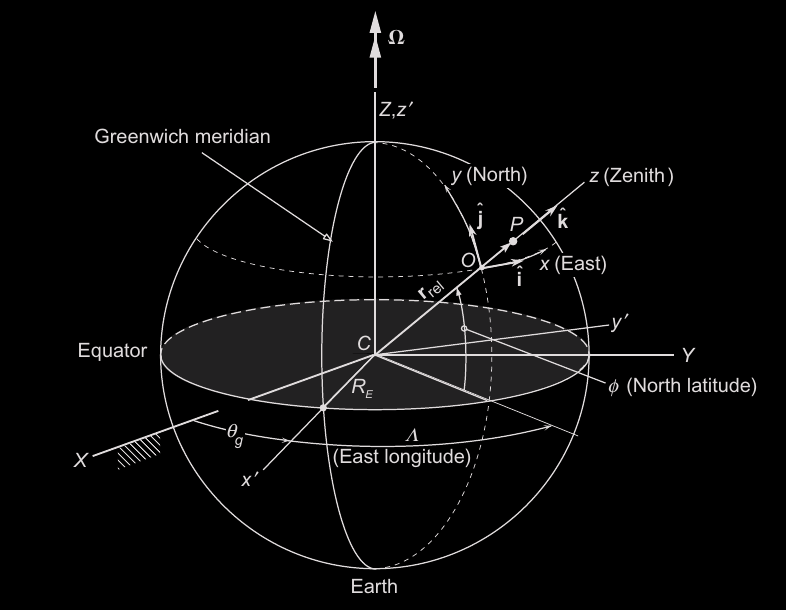

syms RE x y z(t) Lambda(t) phi(t) t i j k Omega(t)

omega = [-diff(phi, t); diff(Lambda, t)*cos(phi); diff(Lambda, t)*sin(phi)]; % angular velocity of the point O, written in its own frame
% omega = subs(omega, [diff(phi, t), diff(Lambda, t)], [sym('phi_dot'), sym('Lambda_dot')])

rrel = [0; 0; (RE + z)]

$$rrel(t) = \left(\begin{array}{c} 0\\ 0\\ \mathrm{RE}+z\left(t\right) \end{array}\right)$$

di_dt = cross(omega, [i; 0; 0])

$$di\_dt(t) = \left(\begin{array}{c} 0\\ i\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\Lambda \left(t\right)\\ -i\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\Lambda \left(t\right) \end{array}\right)$$

dj_dt = cross(omega, [0; j; 0])

$$dj\_dt(t) = \left(\begin{array}{c} -j\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\Lambda \left(t\right)\\ 0\\ -j\,\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

dk_dt = cross(omega, [0; 0; k])

$$dk\_dt(t) = \left(\begin{array}{c} k\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\Lambda \left(t\right)\\ k\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0 \end{array}\right)$$


vrel = diff(rrel, t) + cross(omega, rrel);
% vrel = subs(vrel, diff(z, t), sym('z_dot'))

arel = diff(vrel, t) + cross(omega, vrel)

$$arel(t) = \begin{array}{l} \left(\begin{array}{c} 2\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}z\left(t\right)\,\frac{\partial }{\partial t}\Lambda \left(t\right)+\cos\left(\varphi \left(t\right)\right)\,\left(\mathrm{RE}+z\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Lambda \left(t\right)-2\,\sin\left(\varphi \left(t\right)\right)\,\left(\mathrm{RE}+z\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\Lambda \left(t\right)\\ \left(\mathrm{RE}+z\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\left(\mathrm{RE}+z\left(t\right)\right)\,\sigma_{1}+2\,\frac{\partial }{\partial t}z\left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}z\left(t\right)-\left(\mathrm{RE}+z\left(t\right)\right)\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\sigma_{1}-\left(\mathrm{RE}+z\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\Lambda \left(t\right)\right)}^{2} \end{array}$$

% arel = subs(arel, diff(z, t), sym('z_dot'))

Omega_vec = [0; Omega*cos(phi); Omega*sin(phi)] % angular velocity of earth's rotation

$$Omega\_vec(t) = \left(\begin{array}{c} 0\\ \cos\left(\varphi \left(t\right)\right)\,\Omega \left(t\right)\\ \sin\left(\varphi \left(t\right)\right)\,\Omega \left(t\right) \end{array}\right)$$


vc = 0;
v = vc + vrel + cross(Omega_vec, rrel);

ac = 0;
a = ac + arel + cross(diff(Omega_vec, t), rrel) + cross(Omega_vec, cross(Omega_vec, rrel)) + 2*cross(Omega_vec, vrel);

v = subs(v, [diff(Omega, t), diff(phi, t), diff(Lambda, t), diff(x, t, 2), diff(x, t), diff(y, t, 2), diff(y, t), diff(z, t, 2), diff(z, t)], [sym('Omega_dot'), sym('phi_dot'), sym('Lambda_dot'), sym('x_ddot'), sym('x_dot'), sym('y_ddot'), sym('y_dot'), sym('z_ddot'), sym('z_dot')])

$$v(t) = \left(\begin{array}{c} \cos\left(\varphi \left(t\right)\right)\,\Omega \left(t\right)\,\left(\mathrm{RE}+z\left(t\right)\right)+\dot{\Lambda }\,\cos\left(\varphi \left(t\right)\right)\,\left(\mathrm{RE}+z\left(t\right)\right)\\ \dot{\varphi }\,\left(\mathrm{RE}+z\left(t\right)\right)\\ \dot{z} \end{array}\right)$$

a = simplify(subs(a, [diff(Omega, t), diff(phi, t), diff(Lambda, t), diff(x, t, 2), diff(x, t), diff(y, t, 2), diff(y, t), diff(z, t, 2), diff(z, t)], [sym('Omega_dot'), sym('phi_dot'), sym('Lambda_dot'), sym('x_ddot'), sym('x_dot'), sym('y_ddot'), sym('y_dot'), sym('z_ddot'), sym('z_dot')]))

$$a(t) = \begin{array}{l} \left(\begin{array}{c} \left(\dot{\Omega }\,\cos\left(\varphi \left(t\right)\right)-\dot{\varphi }\,\sin\left(\varphi \left(t\right)\right)\,\Omega \left(t\right)\right)\,\left(\mathrm{RE}+z\left(t\right)\right)+2\,\dot{\Lambda }\,\dot{z}\,\cos\left(\varphi \left(t\right)\right)+2\,\dot{z}\,\cos\left(\varphi \left(t\right)\right)\,\Omega \left(t\right)-2\,\dot{\Lambda }\,\dot{\varphi }\,\sin\left(\varphi \left(t\right)\right)\,\left(\mathrm{RE}+z\left(t\right)\right)-2\,\dot{\varphi }\,\sin\left(\varphi \left(t\right)\right)\,\Omega \left(t\right)\,\left(\mathrm{RE}+z\left(t\right)\right)\\ \frac{\sigma_{2}\,\left(\mathrm{RE}+z\left(t\right)\right)\,{\dot{\Lambda }}^{2}}{2}+\sigma_{2}\,\left(\mathrm{RE}+z\left(t\right)\right)\,\dot{\Lambda }\,\Omega \left(t\right)+\frac{\sigma_{2}\,\left(\mathrm{RE}+z\left(t\right)\right)\,{\Omega \left(t\right)}^{2}}{2}+2\,\dot{\varphi }\,\dot{z}\\ \ddot{z}-{\dot{\varphi }}^{2}\,\left(\mathrm{RE}+z\left(t\right)\right)-{\dot{\Lambda }}^{2}\,\sigma_{1}\,\left(\mathrm{RE}+z\left(t\right)\right)-\sigma_{1}\,{\Omega \left(t\right)}^{2}\,\left(\mathrm{RE}+z\left(t\right)\right)-2\,\dot{\Lambda }\,\sigma_{1}\,\Omega \left(t\right)\,\left(\mathrm{RE}+z\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\varphi \left(t\right)\right)}^{2}\\ \sigma_{2}=\sin\left(2\,\varphi \left(t\right)\right) \end{array}$$